## Connect to the Racecar in Gazebo

rosshutdown

Shutting down global node /matlab_global_node_25927 with NodeURI http://192.168.137.1:50406/


rosinit 192.168.137.134

Initializing global node /matlab_global_node_52087 with NodeURI http://192.168.137.1:51640/


## Load the Map of the Simulation World

Load a binary occupancy grid of the environment in Gazebo. The map is generated by driving racecar inside the  environment. 

load Walker_Interior_OccGrid.mat
map = myOccMap

map =   occupancyMap with properties:

             XWorldLimits: [-17.8147 15.1853]
             YWorldLimits: [-21.9097 16.0903]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [-17.8147 -21.9097]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 15
                 GridSize: [570 495]
             XLocalLimits: [0 33]
             YLocalLimits: [0 38]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [-17.8147 -21.9097]


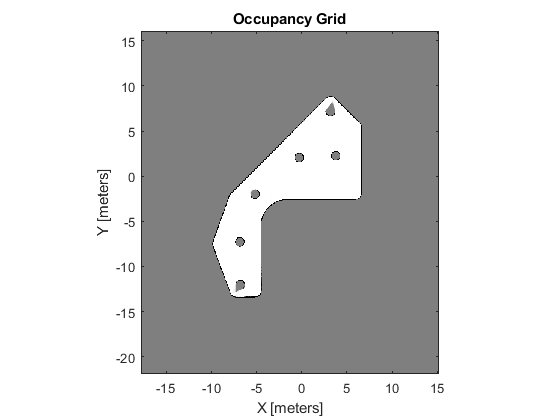

show(map)

## Setup the Laser Sensor Model and Motion Model

odometryModel = odometryMotionModel;
odometryModel.Noise = [0.2 0.2 0.2 0.2];

rangeFinderModel = likelihoodFieldSensorModel;
rangeFinderModel.SensorLimits = [0.45 8];
rangeFinderModel.Map = map;

% Query the Transformation Tree (tf tree) in ROS.
tftree = rostf;
waitForTransform(tftree,'/base_link','/laser');
sensorTransform = getTransform(tftree,'/base_link', '/laser');

% Get the euler rotation angles.
laserQuat = [sensorTransform.Transform.Rotation.W sensorTransform.Transform.Rotation.X ...
    sensorTransform.Transform.Rotation.Y sensorTransform.Transform.Rotation.Z];
laserRotation = quat2eul(laserQuat, 'ZYX');

% Setup the |SensorPose|, which includes the translation along base_link's
% +X, +Y direction in meters and rotation angle along base_link's +Z axis
% in radians.
rangeFinderModel.SensorPose = ...
    [sensorTransform.Transform.Translation.X sensorTransform.Transform.Translation.Y laserRotation(1)];

## Receiving Sensor Measurements and Sending Velocity Commands

Create ROS subscribers for retrieving sensor and odometry measurements from racecar.

laserSub = rossubscriber('/scan');
odomSub = rossubscriber('/vesc/odom');

[velPub,velMsg] = ...
    rospublisher('/vesc/high_level/ackermann_cmd_mux/input/nav_0','ackermann_msgs/AckermannDriveStamped');

## Initialize AMCL Object

Instantiate an AMCL object `amcl`. See [monteCarloLocalization](docid:nav_ref.bu31hfz-1) for more information on the class.

amcl = monteCarloLocalization;
amcl.UseLidarScan = true;

Assign the `MotionModel` and `SensorModel` properties in the `amcl` object.

amcl.MotionModel = odometryModel;
amcl.SensorModel = rangeFinderModel;

amcl.UpdateThresholds = [0.2,0.2,0.2];
amcl.ResamplingInterval = 1;

## Configure AMCL Object for Localization with Initial Pose Estimate.

`amcl.ParticleLimits` defines the lower and upper bound on the number of particles that will be generated during the resampling process. Allowing more particles to be generated may improve the chance of converging to the true robot pose, but has an impact on computation speed and particles may take longer time or even fail to converge. Please refer to the 'KL-D Sampling' section in [1] for computing a reasonable bound value on the number of particles. Note that global localization may need significantly more particles compared to localization with an initial pose estimate. If the robot knows its initial pose with some uncertainty, such additional information can help AMCL localize robots faster with a less number of particles, i.e. you can use a smaller value of upper bound in `amcl.ParticleLimits`.

Now set `amcl.GlobalLocalization` to false and provide an estimated initial pose to AMCL. By doing so, AMCL holds the initial belief that robot's true pose follows a Gaussian distribution with a mean equal to `amcl.InitialPose` and a covariance matrix equal to `amcl.InitialCovariance`. Initial pose estimate should be obtained according to your setup. This example helper retrieves the robot's current true pose from Gazebo.

Please refer to section **Configure AMCL object for global localization** for an example on using global localization.

amcl.ParticleLimits = [500 5000];
amcl.GlobalLocalization = false;
amcl.InitialPose = ExampleHelperAMCLGazeboTruePose_racecar;
amcl.InitialCovariance = eye(3)*0.5;

## Setup Helper for Visualization and Driving Racecar.

Setup ExampleHelperAMCLVisualization to plot the map and update robot's estimated pose, particles, and laser scan readings on the map.

visualizationHelper = ExampleHelperAMCLVisualization(map);

Robot motion is essential for the AMCL algorithm. In this example, we drive Racecar randomly using the ExampleHelperAMCLWanderer class, which drives the robot inside the environment while avoiding obstacles using the [`vectorFieldHistogram`](docid:nav_ref.buv7g7y) class.

wanderHelper = ...
    ExampleHelperAMCLWanderer_ackerman(laserSub, sensorTransform, velPub, velMsg);

## Localization Procedure

The AMCL algorithm is updated with odometry and sensor readings at each time step when the robot is moving around. Please allow a few seconds before particles are initialized and plotted in the figure. In this example we will run `numUpdates` AMCL updates. If the robot doesn't converge to the correct robot pose, consider using a larger `numUpdates`.

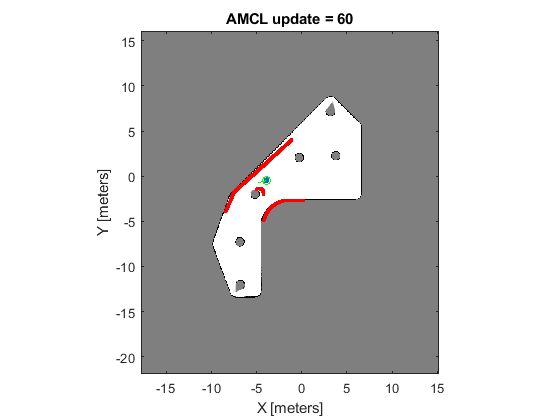

numUpdates = 60;
i = 0;
while i < numUpdates
    % Receive laser scan and odometry message.
    scanMsg = receive(laserSub);
    odompose = odomSub.LatestMessage;
    
    % Create lidarScan object to pass to the AMCL object.
    scan = lidarScan(scanMsg);
    
    % For sensors that are mounted upside down, you need to reverse the
    % order of scan angle readings using 'flip' function.
    
    % Compute robot's pose [x,y,yaw] from odometry message.
    odomQuat = [odompose.Pose.Pose.Orientation.W, odompose.Pose.Pose.Orientation.X, ...
        odompose.Pose.Pose.Orientation.Y, odompose.Pose.Pose.Orientation.Z];
    odomRotation = quat2eul(odomQuat);
    pose = [odompose.Pose.Pose.Position.X, odompose.Pose.Pose.Position.Y odomRotation(1)];
    
    % Update estimated robot's pose and covariance using new odometry and
    % sensor readings.
    [isUpdated,estimatedPose, estimatedCovariance] = amcl(pose, scan);
    
    % Drive robot to next pose.
    wander(wanderHelper);
    
    % Plot the robot's estimated pose, particles and laser scans on the map.
    if isUpdated
        i = i + 1;
        plotStep(visualizationHelper, amcl, estimatedPose, scan, i)
    end
    
end

## Stop the Racecar and Shutdown ROS in MATLAB

stop(wanderHelper);
rosshutdown